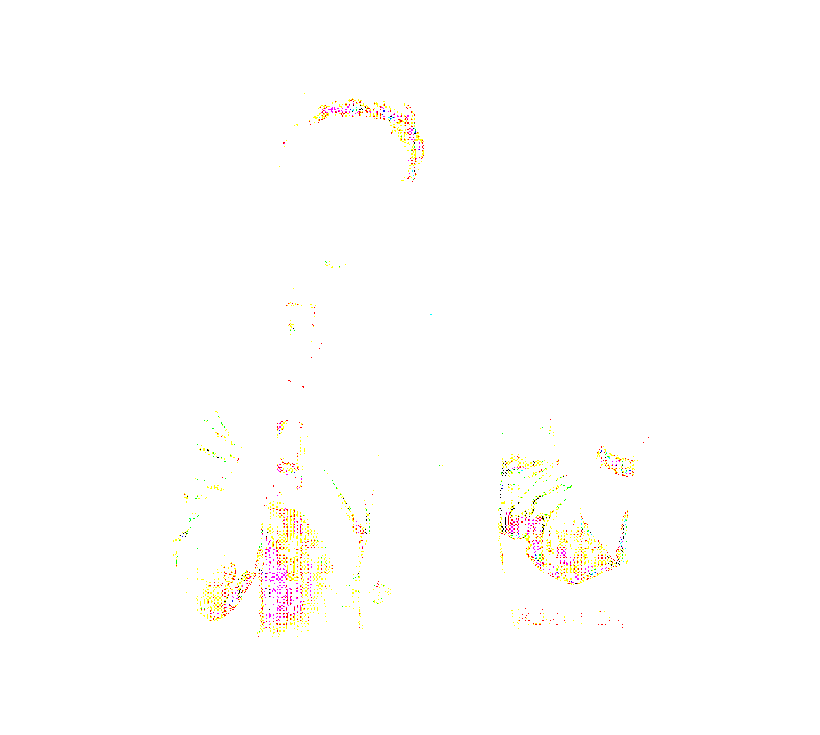

image=imread('me.png');
zoom=3;
[r,c,d]=size(image);

rn=floor(r*zoom);
cn=floor(c*zoom);
im_zoom = zeros(rn,cn,d);
s=zoom;
for i = 1:rn;
    x=i/s;
    near_i=cast(round(x),'uint16');
    if near_i==0
        near_i=1;
    end
    for j =1:cn;
        y=j/s;
        near_j=cast(round(y),'uint16');
        if near_j==0
            near_j=1;
        end
        im_zoom(i,j,:) = image(near_i,near_j,:);
    end
end
imshow(im_zoom);